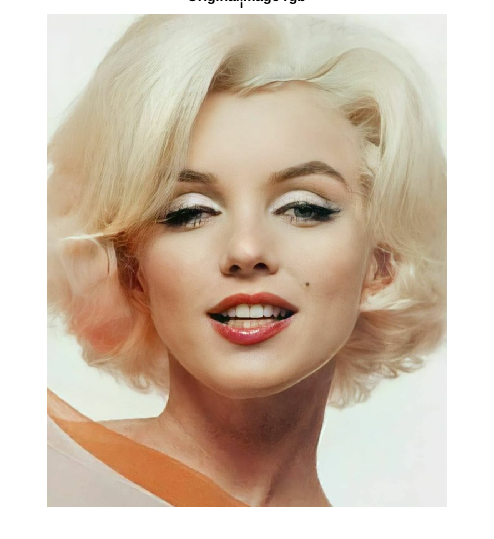

clear  % delete the workspace
clc    % refresh the command window
close all hidden 
img = imread('/home/srb-jarvis/fh_3dimgprocessing/2. Labtask/popart.jpg');
imshow(img), title("Original_image rgb");


% scaling the original image
[height, width, channel] = size(img)

height = 888

width = 720

channel = 3

max_val = max(height, width)

max_val = 888

scale = 512/max_val

scale = 0.5766

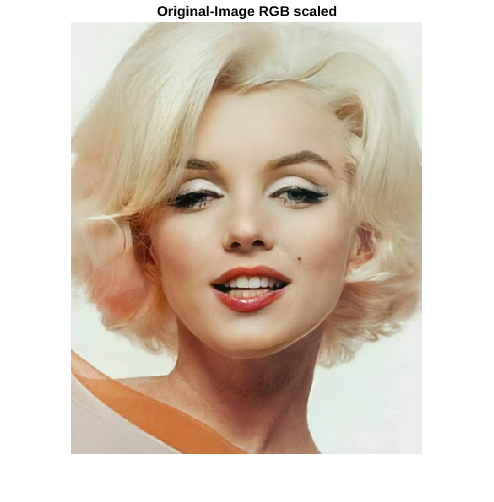

img_scaled = imresize(img,scale);
scled_size = size(img_scaled);
imshow(img_scaled), title("Original-Image RGB scaled")

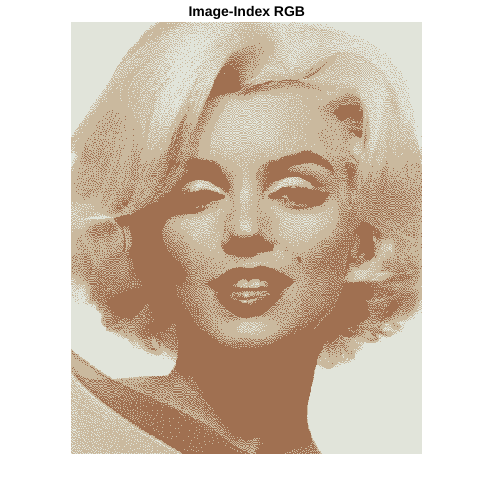

% Generation of index image from rgb image
[img_indx, map] = rgb2ind(img_scaled, 3);
imshow(img_indx, map), title("Image-Index RGB")


% Defining the color map for index image pop-art effect
c_map1 = [192,220,110 ; 80,120,165 ; 110,80,65]./255;
c_map2 = [90,65,170 ; 120,210,60 ; 220,190,210]./255;
c_map3 = [192,65,230 ; 180,220,65 ; 110,120,240]./255;
c_map4 = [40,220,80 ; 120,100,220 ; 30,180,165]./255;

% Conversion of Index image back to RGB image with user defined color map
image_1 = ind2rgb(img_indx, c_map1);
image_2 = ind2rgb(img_indx, c_map2);
image_3 = ind2rgb(img_indx, c_map3);
image_4 = ind2rgb(img_indx, c_map4);

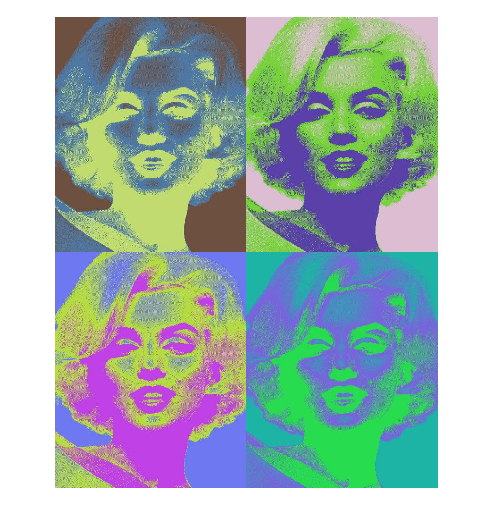

% Generation of pop art collage and display
imwrite(image_1, 'image_1.jpg');
imwrite(image_2, 'image_2.jpg');
imwrite(image_3, 'image_3.jpg');
imwrite(image_4, 'image_4.jpg');
pictures = {'image_1.jpg' 'image_2.jpg' 'image_3.jpg' 'image_4.jpg'};
disp("")
montage(pictures, 'Size', [2 2]);
group = getframe(gca);

imwrite(group.cdata, 'popArt5.jpg');